Call the Summary Table

LatexPlots
load SummTable_OB
filter = find((SummTable.hazlvl <= 3.0));
SummTable = SummTable(filter, :)

SummTable = 960×20 table
    hazlvl    cf       spd       bridgemodel     pga        pgv         pbd         pbv       pba        pbrot         pcd         pwd        pcrot        pwrot        purot        pcha      pcva     drdis      drcase    gm
    ______    __    _________    ___________    ______    _______    _________    _______    ______    __________    ________    ________    ________    _________    

Plot of PGA vs Derailments

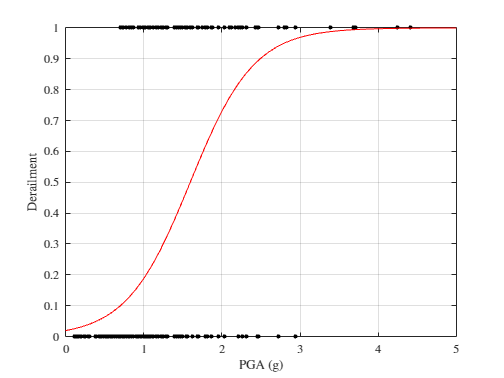

close
NotSortedData = [SummTable.pga/9.81, SummTable.drcase];
SortedData = sortrows(NotSortedData);

mdl = fitglm(SortedData(:,1), SortedData(:,2), "Distribution", "binomial");
xnew = (0:0.1:5.0)';
ynew = predict(mdl, xnew);

plot(SummTable.pga/9.81, SummTable.drcase, 'k.', ...
    xnew, ynew, 'r', 'MarkerSize', 10.0), grid on, xlabel('PGA (g)'), ylabel('Derailment'), xlim([0 5])

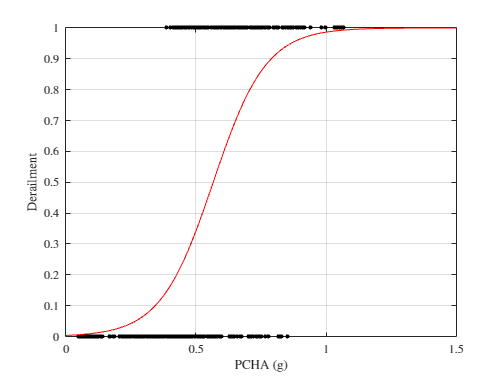

close
NotSortedData = [SummTable.pcha/9.81, SummTable.drcase];
SortedData = sortrows(NotSortedData);

winsize = 0.25;
winres = 0.02;
xvals = 0:winres:max(SortedData(:,1));

pvals = [];
loc = 1;
for xcoor = xvals
    inflim = xcoor;
    suplim = xcoor + winsize;
    indices = find((SortedData(:, 1) >= inflim) .* (SortedData(:, 1) < suplim));
    pvals(loc) = sum(SortedData(indices, 2)) / length(indices);
    loc = loc + 1;
end


mdl = fitglm(SortedData(:,1), SortedData(:,2), "Distribution", "binomial");
xnew = (0:0.01:1.5)';
ynew = predict(mdl, xnew);


plot(SummTable.pcha/9.81, SummTable.drcase, 'k.', ...
    xnew, ynew, 'r', 'MarkerSize', 10.0), grid on, xlabel('PCHA (g)'), ylabel('Derailment')

close
filter = find((SummTable.bridgemodel == 0.0) .* (SummTable.cf == 1.0));
NotSortedData = [SummTable(filter,:).pbv, SummTable(filter,:).drcase];
SortedData = sortrows(NotSortedData);

winsize = 0.25;
winres = 0.05;
xvals = 0:winres:max(SortedData(:,1));

pvals = [];
loc = 1;
for xcoor = xvals
    inflim = xcoor;
    suplim = xcoor + winsize;
    indices = find((SortedData(:, 1) >= inflim) .* (SortedData(:, 1) < suplim));
    pvals(loc) = sum(SortedData(indices, 2)) / length(indices);
    loc = loc + 1;
end

mdl = fitglm(SortedData(:,1), SortedData(:,2), "Distribution", "binomial");
xnew = (0:0.01:5)';
ynew = predict(mdl, xnew);

% Plot Nonlinear Model
plot(SummTable(filter,:).pbv, SummTable(filter,:).drcase, 'r.', ...
    xnew, ynew, 'r', 'MarkerSize', 15.0), grid on, xlabel('PBV (m/s)'), ylabel('Derailment')
hold on

filter = find((SummTable.bridgemodel == 1.0) .* (SummTable.cf == 1.0));
NotSortedData = [SummTable(filter,:).pbv, SummTable(filter,:).drcase];
SortedData = sortrows(NotSortedData);

mdl = fitglm(SortedData(:,1), SortedData(:,2), "Distribution", "binomial")

mdl = Generalized linear regression model:
    logit(y) ~ 1 + x1
    Distribution = Binomial

Estimated Coefficients:
                   Estimate      SE        tStat       pValue  
                   ________    _______    _______    __________

    (Intercept)    -6.8053     0.91983    -7.3984    1.3782e-13
    x1              4.2477     0.61252     6.9348    4.0686e-12


240 observations, 238 error degrees of freedom
Dispersion: 1
Chi^2-statistic vs. constant model: 133, p-value = 8.03e-31

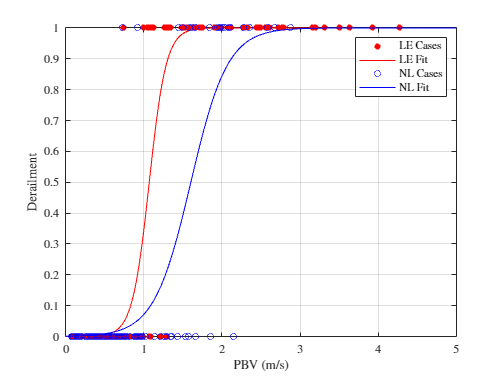

xnew = (0:0.01:5)';
ynew = predict(mdl, xnew);

% Plot Linear Model
plot(SummTable(filter, :).pbv, SummTable(filter, :).drcase, 'bo', ...
    xnew, ynew, 'b-', 'MarkerSize', 5.0), grid on, xlabel('PBV (m/s)'), ylabel('Derailment'), xlim([0 5])
legend('LE Cases', 'LE Fit', 'NL Cases', 'NL Fit')

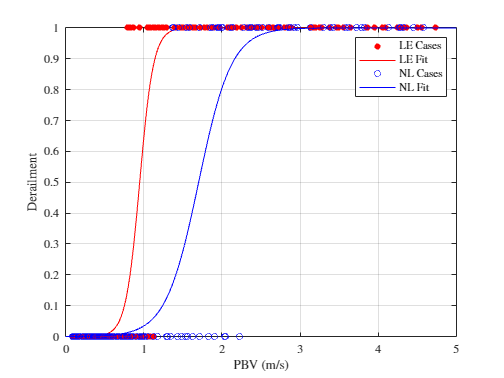

close
filter = find((SummTable.bridgemodel == 0.0) .* (SummTable.cf == 0.0));
NotSortedData = [SummTable(filter,:).pbv, SummTable(filter,:).drcase];
SortedData = sortrows(NotSortedData);

winsize = 0.25;
winres = 0.05;
xvals = 0:winres:max(SortedData(:,1));

pvals = [];
loc = 1;
for xcoor = xvals
    inflim = xcoor;
    suplim = xcoor + winsize;
    indices = find((SortedData(:, 1) >= inflim) .* (SortedData(:, 1) < suplim));
    pvals(loc) = sum(SortedData(indices, 2)) / length(indices);
    loc = loc + 1;
end

mdl = fitglm(SortedData(:,1), SortedData(:,2), "Distribution", "binomial");
xnew = (0:0.01:6.0)';
ynew = predict(mdl, xnew);

% Plot Nonlinear Model
plot(SummTable(filter,:).pbv, SummTable(filter,:).drcase, 'r.', ...
    xnew, ynew, 'r', 'MarkerSize', 15.0), grid on, xlabel('PBV (m/s)'), ylabel('Derailment')
hold on

filter = find((SummTable.bridgemodel == 1.0) .* (SummTable.cf == 0.0));
NotSortedData = [SummTable(filter,:).pbv, SummTable(filter,:).drcase];
SortedData = sortrows(NotSortedData);

winsize = 0.25;
winres = 0.05;
xvals = 0:winres:max(SortedData(:,1));

pvals = [];
loc = 1;
for xcoor = xvals
    inflim = xcoor;
    suplim = xcoor + winsize;
    indices = find((SortedData(:, 1) >= inflim) .* (SortedData(:, 1) < suplim));
    pvals(loc) = sum(SortedData(indices, 2)) / length(indices);
    loc = loc + 1;
end

mdl = fitglm(SortedData(:,1), SortedData(:,2), "Distribution", "binomial");
xnew = (0:0.01:6.0)';
ynew = predict(mdl, xnew);

% Plot Linear Model
plot(SummTable(filter, :).pbv, SummTable(filter, :).drcase, 'bo', ...
    xnew, ynew, 'b-', 'MarkerSize', 5.0), grid on, xlabel('PBV (m/s)'), ylabel('Derailment'), xlim([0 5])
legend('LE Cases', 'LE Fit', 'NL Cases', 'NL Fit')

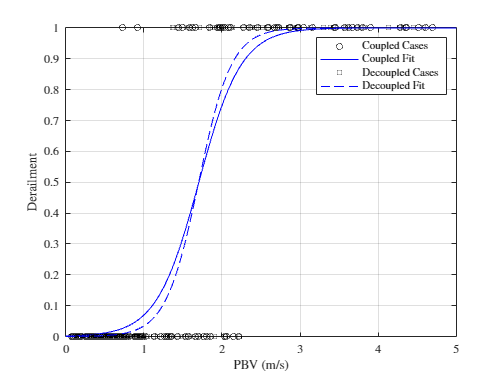

close
filter = find((SummTable.bridgemodel == 1.0) .* (SummTable.cf == 1.0));
NotSortedData = [SummTable(filter,:).pbv, SummTable(filter,:).drcase];
SortedData = sortrows(NotSortedData);

winsize = 0.25;
winres = 0.05;
xvals = 0:winres:max(SortedData(:,1));

pvals = [];
loc = 1;
for xcoor = xvals
    inflim = xcoor;
    suplim = xcoor + winsize;
    indices = find((SortedData(:, 1) >= inflim) .* (SortedData(:, 1) < suplim));
    pvals(loc) = sum(SortedData(indices, 2)) / length(indices);
    loc = loc + 1;
end

mdl = fitglm(SortedData(:,1), SortedData(:,2), "Distribution", "binomial");
xnew = (0:0.01:6.0)';
ynew = predict(mdl, xnew);

% Plot Nonlinear Model
plot(SummTable(filter,:).pbv, SummTable(filter,:).drcase, 'ko', ...
    xnew, ynew, 'b-', 'MarkerSize', 5.0), grid on, xlabel('PBV (m/s)'), ylabel('Derailment')
hold on

filter = find((SummTable.bridgemodel == 1.0) .* (SummTable.cf == 0.0));
NotSortedData = [SummTable(filter,:).pbv, SummTable(filter,:).drcase];
SortedData = sortrows(NotSortedData);

winsize = 0.25;
winres = 0.05;
xvals = 0:winres:max(SortedData(:,1));

pvals = [];
loc = 1;
for xcoor = xvals
    inflim = xcoor;
    suplim = xcoor + winsize;
    indices = find((SortedData(:, 1) >= inflim) .* (SortedData(:, 1) < suplim));
    pvals(loc) = sum(SortedData(indices, 2)) / length(indices);
    loc = loc + 1;
end

mdl = fitglm(SortedData(:,1), SortedData(:,2), "Distribution", "binomial");
xnew = (0:0.01:12.0)';
ynew = predict(mdl, xnew);

% Plot Linear Model
plot(SummTable(filter, :).pbv, SummTable(filter, :).drcase, 'ks', ...
    xnew, ynew, 'b--', 'MarkerSize', 5.0), grid on, xlabel('PBV (m/s)'), ylabel('Derailment'), xlim([0 5])
legend('Coupled Cases', 'Coupled Fit', 'Decoupled Cases', 'Decoupled Fit')

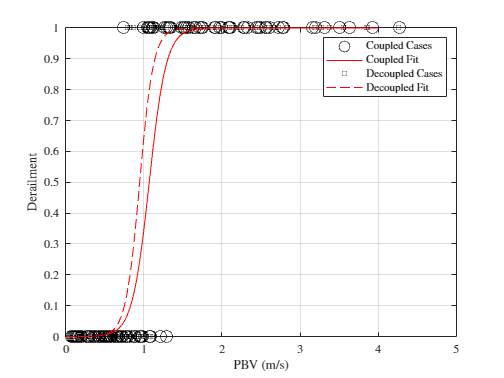

close
filter = find((SummTable.bridgemodel == 0.0) .* (SummTable.cf == 1.0));
NotSortedData = [SummTable(filter,:).pbv, SummTable(filter,:).drcase];
SortedData = sortrows(NotSortedData);

winsize = 0.25;
winres = 0.05;
xvals = 0:winres:max(SortedData(:,1));

pvals = [];
loc = 1;
for xcoor = xvals
    inflim = xcoor;
    suplim = xcoor + winsize;
    indices = find((SortedData(:, 1) >= inflim) .* (SortedData(:, 1) < suplim));
    pvals(loc) = sum(SortedData(indices, 2)) / length(indices);
    loc = loc + 1;
end

mdl = fitglm(SortedData(:,1), SortedData(:,2), "Distribution", "binomial");
xnew = (0:0.01:4.0)';
ynew = predict(mdl, xnew);

% Plot Nonlinear Model
plot(SummTable(filter,:).pbv, SummTable(filter,:).drcase, 'ko', ...
    xnew, ynew, 'r-', 'MarkerSize', 10.0), grid on, xlabel('PBV (m/s)'), ylabel('Derailment')
hold on

filter = find((SummTable.bridgemodel == 0.0) .* (SummTable.cf == 0.0));
NotSortedData = [SummTable(filter,:).pbv, SummTable(filter,:).drcase];
SortedData = sortrows(NotSortedData);

winsize = 0.25;
winres = 0.05;
xvals = 0:winres:max(SortedData(:,1));

pvals = [];
loc = 1;
for xcoor = xvals
    inflim = xcoor;
    suplim = xcoor + winsize;
    indices = find((SortedData(:, 1) >= inflim) .* (SortedData(:, 1) < suplim));
    pvals(loc) = sum(SortedData(indices, 2)) / length(indices);
    loc = loc + 1;
end

mdl = fitglm(SortedData(:,1), SortedData(:,2), "Distribution", "binomial");
xnew = (0:0.01:4.0)';
ynew = predict(mdl, xnew);

% Plot Linear Model
plot(SummTable(filter, :).pbv, SummTable(filter, :).drcase, 'ks', ...
    xnew, ynew, 'r--', 'MarkerSize', 5.0), grid on, xlabel('PBV (m/s)'), ylabel('Derailment'), xlim([0 5])
legend('Coupled Cases', 'Coupled Fit', 'Decoupled Cases', 'Decoupled Fit')

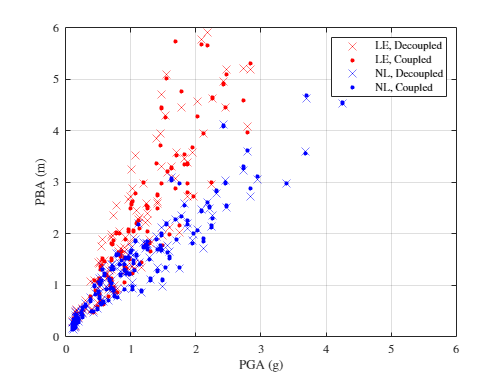

close
indices1 = find((SummTable.bridgemodel == 0.0).*(SummTable.cf == 0.0));  % Linear Elastic, Decoupled
indices2 = find((SummTable.bridgemodel == 0.0).*(SummTable.cf == 1.0));  % Linear Elastic, Coupled
indices3 = find((SummTable.bridgemodel == 1.0).*(SummTable.cf == 0.0));  % Nonlinear, Decoupled
indices4 = find((SummTable.bridgemodel == 1.0).*(SummTable.cf == 1.0));  % Nonlinear, Coupled


plot(SummTable(indices1,:).pga/9.81, SummTable(indices1,:).pba/9.81, 'rx', ...
     SummTable(indices2,:).pga/9.81, SummTable(indices2,:).pba/9.81, 'r.', ...
     SummTable(indices3,:).pga/9.81, SummTable(indices3,:).pba/9.81, 'bx', ...
     SummTable(indices4,:).pga/9.81, SummTable(indices4,:).pba/9.81, 'b.','MarkerSize', 10.0)

xlabel('PGA (g)'), ylabel('PBA (m)'), legend('LE, Decoupled', 'LE, Coupled', 'NL, Decoupled', 'NL, Coupled')

axis([0, 6, 0, 6])
grid on

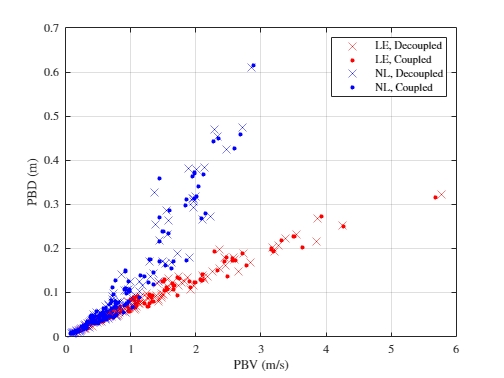

close
indices1 = find((SummTable.bridgemodel == 0.0).*(SummTable.cf == 0.0));  % Linear Elastic, Decoupled
indices2 = find((SummTable.bridgemodel == 0.0).*(SummTable.cf == 1.0));  % Linear Elastic, Coupled
indices3 = find((SummTable.bridgemodel == 1.0).*(SummTable.cf == 0.0));  % Nonlinear, Decoupled
indices4 = find((SummTable.bridgemodel == 1.0).*(SummTable.cf == 1.0));  % Nonlinear, Coupled


plot(SummTable(indices1,:).pbv, SummTable(indices1,:).pbd, 'rx', ...
     SummTable(indices2,:).pbv, SummTable(indices2,:).pbd, 'r.', ...
     SummTable(indices3,:).pbv, SummTable(indices3,:).pbd, 'bx', ...
     SummTable(indices4,:).pbv, SummTable(indices4,:).pbd, 'b.','MarkerSize', 10.0)

xlabel('PBV (m/s)'), ylabel('PBD (m)'), legend('LE, Decoupled', 'LE, Coupled', 'NL, Decoupled', 'NL, Coupled')

%axis([0, 3, 0, 3])
grid on

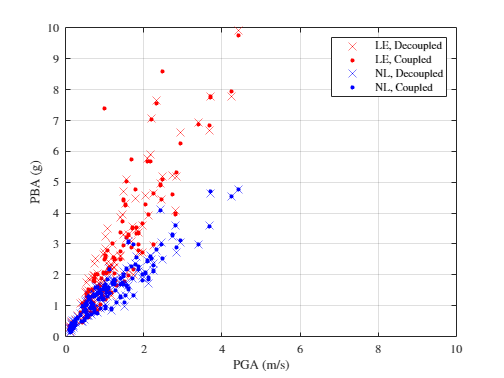

close

indices1 = find((SummTable.bridgemodel == 0.0).*(SummTable.cf == 0.0));  % Linear Elastic, Decoupled
indices2 = find((SummTable.bridgemodel == 0.0).*(SummTable.cf == 1.0));  % Linear Elastic, Coupled
indices3 = find((SummTable.bridgemodel == 1.0).*(SummTable.cf == 0.0));  % Nonlinear, Decoupled
indices4 = find((SummTable.bridgemodel == 1.0).*(SummTable.cf == 1.0));  % Nonlinear, Coupled


plot(SummTable(indices1,:).pga/9.81, SummTable(indices1,:).pba/9.81, 'rx', ...
     SummTable(indices2,:).pga/9.81, SummTable(indices2,:).pba/9.81, 'r.', ...
     SummTable(indices3,:).pga/9.81, SummTable(indices3,:).pba/9.81, 'bx', ...
     SummTable(indices4,:).pga/9.81, SummTable(indices4,:).pba/9.81, 'b.','MarkerSize', 10.0)

xlabel('PGA (m/s)'), ylabel('PBA (g)'), legend('LE, Decoupled', 'LE, Coupled', 'NL, Decoupled', 'NL, Coupled')

axis([0, 10, 0, 10])
grid on

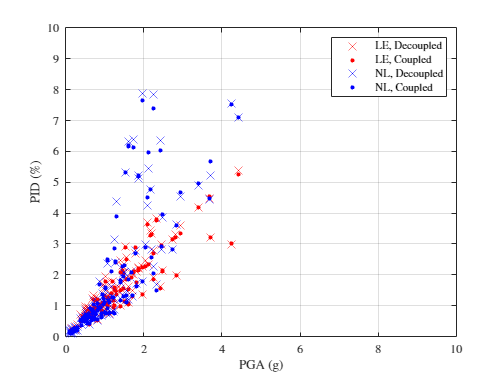

close

indices1 = find((SummTable.bridgemodel == 0.0).*(SummTable.cf == 0.0));  % Linear Elastic, Decoupled
indices2 = find((SummTable.bridgemodel == 0.0).*(SummTable.cf == 1.0));  % Linear Elastic, Coupled
indices3 = find((SummTable.bridgemodel == 1.0).*(SummTable.cf == 0.0));  % Nonlinear, Decoupled
indices4 = find((SummTable.bridgemodel == 1.0).*(SummTable.cf == 1.0));  % Nonlinear, Coupled


plot(SummTable(indices1,:).pga/9.81, SummTable(indices1,:).pbd / 6 * 100, 'rx', ...
     SummTable(indices2,:).pga/9.81, SummTable(indices2,:).pbd / 6 * 100, 'r.', ...
     SummTable(indices3,:).pga/9.81, SummTable(indices3,:).pbd / 6 * 100, 'bx', ...
     SummTable(indices4,:).pga/9.81, SummTable(indices4,:).pbd / 6 * 100, 'b.','MarkerSize', 10.0)

xlabel('PGA (g)'), ylabel('PID (\%)'), legend('LE, Decoupled', 'LE, Coupled', 'NL, Decoupled', 'NL, Coupled')


axis([0, 10, 0, 10])
grid on

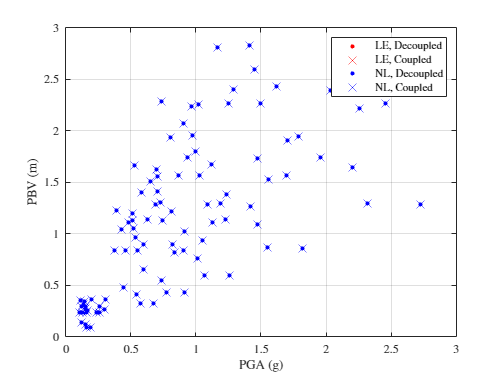

close

indices1 = find((SummTable.bridgemodel == 0.0).*(SummTable.cf == 0.0));  % Linear Elastic, Decoupled
indices2 = find((SummTable.bridgemodel == 0.0).*(SummTable.cf == 1.0));  % Nonlinear, Decoupled
indices3 = find((SummTable.bridgemodel == 1.0).*(SummTable.cf == 0.0));  % Linear Elastic, Coupled
indices4 = find((SummTable.bridgemodel == 1.0).*(SummTable.cf == 1.0));  % Nonlinear, Coupled

plot(SummTable(indices1,:).pga/9.81, SummTable(indices1,:).pgv, 'r.', ...
     SummTable(indices2,:).pga/9.81, SummTable(indices2,:).pgv, 'rx', ...
     SummTable(indices3,:).pga/9.81, SummTable(indices3,:).pgv, 'b.', ...
     SummTable(indices4,:).pga/9.81, SummTable(indices4,:).pgv, 'bx','MarkerSize', 10.0)

xlabel('PGA (g)'), ylabel('PBV (m)'), legend('LE, Decoupled', 'LE, Coupled', 'NL, Decoupled', 'NL, Coupled')


axis([0, 3, 0, 3])
grid on

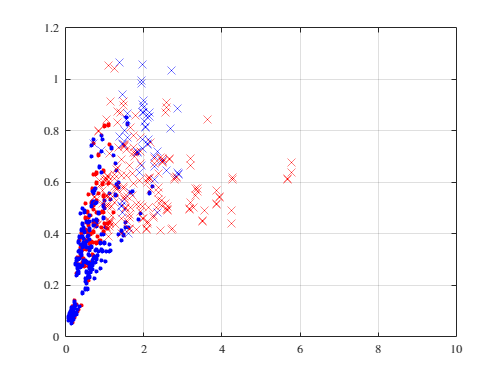

close
indices1 = find((SummTable.bridgemodel == 0.0).*(SummTable.drcase == 0.0));  % Linear Elastic, Decoupled
indices2 = find((SummTable.bridgemodel == 1.0).*(SummTable.drcase == 0.0));  % Nonlinear, Decoupled
indices3 = find((SummTable.bridgemodel == 0.0).*(SummTable.drcase == 1.0));  % Linear Elastic, Coupled
indices4 = find((SummTable.bridgemodel == 1.0).*(SummTable.drcase == 1.0));  % Nonlinear, Coupled
plot(SummTable(indices1,:).pbv, SummTable(indices1,:).pcha/9.81, 'r.', ...
     SummTable(indices2,:).pbv, SummTable(indices2,:).pcha/9.81, 'b.', ...
     SummTable(indices3,:).pbv, SummTable(indices3,:).pcha/9.81, 'rx', ...
     SummTable(indices4,:).pbv, SummTable(indices4,:).pcha/9.81, 'bx','MarkerSize', 10.0)
xlim([0 10])
grid on

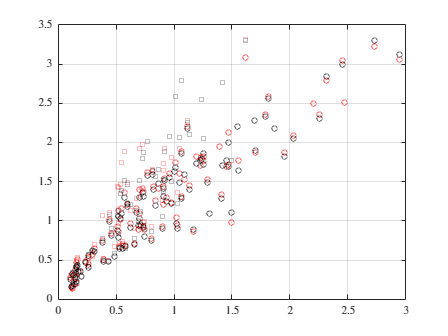

close
indices1 = find((SummTable.bridgemodel == 0.0).*(SummTable.drcase == 0.0).*(SummTable.cf == 0.0));  % Linear Elastic, Decoupled
indices2 = find((SummTable.bridgemodel == 1.0).*(SummTable.drcase == 0.0).*(SummTable.cf == 0.0));  % Nonlinear, Decoupled
indices3 = find((SummTable.bridgemodel == 0.0).*(SummTable.drcase == 0.0).*(SummTable.cf == 1.0));  % Linear Elastic, Coupled
indices4 = find((SummTable.bridgemodel == 1.0).*(SummTable.drcase == 0.0).*(SummTable.cf == 1.0));  % Nonlinear, Coupled
plot(SummTable(indices1,:).pga/9.81, SummTable(indices1,:).pba/9.81, 'rs', ...
     SummTable(indices2,:).pga/9.81, SummTable(indices2,:).pba/9.81, 'ro', ...
     SummTable(indices3,:).pga/9.81, SummTable(indices3,:).pba/9.81, 'ks', ...
     SummTable(indices4,:).pga/9.81, SummTable(indices4,:).pba/9.81, 'ko','MarkerSize', 5.0), grid

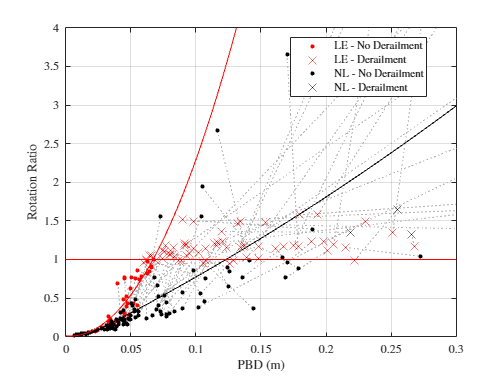

close all
cfac = 0.0;
indices1 = find((SummTable.bridgemodel == 0.0).*(SummTable.drcase == 0.0).*(SummTable.cf == cfac).*(SummTable.spd > 10));  % Linear Elastic, Decoupled
indices2 = find((SummTable.bridgemodel == 0.0).*(SummTable.drcase == 1.0).*(SummTable.cf == cfac).*(SummTable.spd > 10));  % Nonlinear, Decoupled
indices3 = find((SummTable.bridgemodel == 1.0).*(SummTable.drcase == 0.0).*(SummTable.cf == cfac).*(SummTable.spd > 10));  % Linear Elastic, Coupled
indices4 = find((SummTable.bridgemodel == 1.0).*(SummTable.drcase == 1.0).*(SummTable.cf == cfac).*(SummTable.spd > 10));  % Nonlinear, Coupled

indices5 = find((SummTable.bridgemodel == 0.0).*(SummTable.cf == cfac).*(SummTable.spd > 10));
indices6 = find((SummTable.bridgemodel == 1.0).*(SummTable.cf == cfac).*(SummTable.spd > 10));


peakrot = deg2rad(0.836);

pfit1 = polyfit(SummTable(indices1,:).pbd, SummTable(indices1,:).purot, 2);
pfit2 = polyfit(SummTable(indices3,:).pbd, SummTable(indices3,:).purot, 2);

for i = 1:length(indices6)
    plot([SummTable(indices5(i),:).pbd, SummTable(indices6(i),:).pbd], [SummTable(indices5(i),:).purot, SummTable(indices6(i),:).purot]/peakrot, ':', ...
        linewidth=0.05, HandleVisibility='off', Color=[0.7, 0.7, 0.7]), hold on
end

plot(SummTable(indices1,:).pbd, SummTable(indices1,:).purot/peakrot, 'r.', ...
     SummTable(indices2,:).pbd, SummTable(indices2,:).purot/peakrot, 'rx', ...
     SummTable(indices3,:).pbd, SummTable(indices3,:).purot/peakrot, 'k.', ...
     SummTable(indices4,:).pbd, SummTable(indices4,:).purot/peakrot, 'kx', 'MarkerSize', 10.0)
xvals = 0:0.001:0.3;
plot(xvals, polyval(pfit1, xvals)/peakrot, 'r', ...
     xvals, polyval(pfit2, xvals)/peakrot, 'k', ...
     xvals, ones(length(xvals)), 'r-');
axis([0 0.3 0 4.0])
grid, legend('LE - No Derailment', 'LE - Derailment', 'NL - No Derailment', 'NL - Derailment', Location='best'), xlabel('PBD (m)'), ylabel('Rotation Ratio')

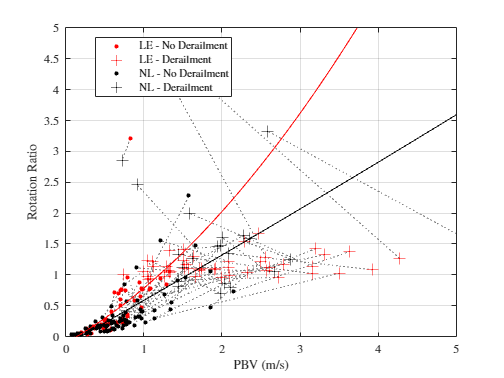

close all
cfac = 1.0;  % Only coupled cases
indices1 = find((SummTable.bridgemodel == 0.0).*(SummTable.drcase == 0.0).*(SummTable.cf == cfac).*(SummTable.spd < 1));  % Linear No derail
indices2 = find((SummTable.bridgemodel == 0.0).*(SummTable.drcase == 1.0).*(SummTable.cf == cfac).*(SummTable.spd < 1));  % Linear Derail
indices3 = find((SummTable.bridgemodel == 1.0).*(SummTable.drcase == 0.0).*(SummTable.cf == cfac).*(SummTable.spd < 1));  % Nonlinear No derail
indices4 = find((SummTable.bridgemodel == 1.0).*(SummTable.drcase == 1.0).*(SummTable.cf == cfac).*(SummTable.spd < 1));  % Nonlinear derail

indices5 = find((SummTable.bridgemodel == 0.0).*(SummTable.cf == cfac).*(SummTable.spd < 1));  % Nonlinear, all
indices6 = find((SummTable.bridgemodel == 1.0).*(SummTable.cf == cfac).*(SummTable.spd < 1));  % Linear, all

peakrot = deg2rad(0.836);

pfit1 = polyfit(SummTable(indices1,:).pbv, SummTable(indices1,:).purot, 2);
pfit2 = polyfit(SummTable(indices3,:).pbv, SummTable(indices3,:).purot, 2);

for i = 1:length(indices6)
    line_color = sign(SummTable(indices5(i),:).pbv - SummTable(indices6(i),:).pbv);
    plot([SummTable(indices5(i),:).pbv, SummTable(indices6(i),:).pbv], [SummTable(indices5(i),:).purot, SummTable(indices6(i),:).purot]/peakrot, ':', ...
        linewidth=0.05, HandleVisibility='off', Color=[0.5, 0.5, 0.5]), hold on
end

plot(SummTable(indices1,:).pbv, SummTable(indices1,:).purot/peakrot, 'r.', ...
     SummTable(indices2,:).pbv, SummTable(indices2,:).purot/peakrot, 'r+', ...
     SummTable(indices3,:).pbv, SummTable(indices3,:).purot/peakrot, 'k.', ...
     SummTable(indices4,:).pbv, SummTable(indices4,:).purot/peakrot, 'k+', 'MarkerSize', 10.0)
xvals = 0:0.01:14.0;
plot(xvals, polyval(pfit1, xvals)/peakrot, 'r', ...
     xvals, polyval(pfit2, xvals)/peakrot, 'k')
axis([0 5.0 0 5.0])
grid, legend('LE - No Derailment', 'LE - Derailment', 'NL - No Derailment', 'NL - Derailment', Location='best'), xlabel('PBV (m/s)'), ylabel('Rotation Ratio')

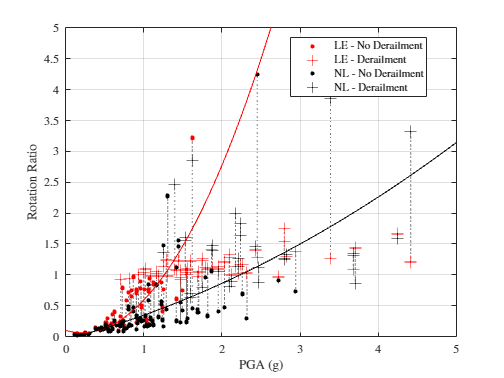

close all
cfac = 1.0;  % Only coupled cases
indices1 = find((SummTable.bridgemodel == 0.0).*(SummTable.drcase == 0.0).*(SummTable.cf == cfac));  % Linear No derail
indices2 = find((SummTable.bridgemodel == 0.0).*(SummTable.drcase == 1.0).*(SummTable.cf == cfac));  % Linear Derail
indices3 = find((SummTable.bridgemodel == 1.0).*(SummTable.drcase == 0.0).*(SummTable.cf == cfac));  % Nonlinear No derail
indices4 = find((SummTable.bridgemodel == 1.0).*(SummTable.drcase == 1.0).*(SummTable.cf == cfac));  % Nonlinear derail

indices5 = find((SummTable.bridgemodel == 0.0).*(SummTable.cf == cfac));  % Nonlinear, all
indices6 = find((SummTable.bridgemodel == 1.0).*(SummTable.cf == cfac));  % Linear, all

peakrot = deg2rad(0.836);

pfit1 = polyfit(SummTable(indices1,:).pga/9.81, SummTable(indices1,:).purot, 2);
pfit2 = polyfit(SummTable(indices3,:).pga/9.81, SummTable(indices3,:).purot, 2);

for i = 1:length(indices6)
    line_color = sign(SummTable(indices5(i),:).pga - SummTable(indices6(i),:).pga);
    plot([SummTable(indices5(i),:).pga/9.81, SummTable(indices6(i),:).pga/9.81], [SummTable(indices5(i),:).purot, SummTable(indices6(i),:).purot]/peakrot, ':', ...
        linewidth=0.05, HandleVisibility='off', Color=[0.5, 0.5, 0.5]), hold on
end

plot(SummTable(indices1,:).pga/9.81, SummTable(indices1,:).purot/peakrot, 'r.', ...
     SummTable(indices2,:).pga/9.81, SummTable(indices2,:).purot/peakrot, 'r+', ...
     SummTable(indices3,:).pga/9.81, SummTable(indices3,:).purot/peakrot, 'k.', ...
     SummTable(indices4,:).pga/9.81, SummTable(indices4,:).purot/peakrot, 'k+', 'MarkerSize', 10.0)
xvals = 0:0.01:14.0;
plot(xvals, polyval(pfit1, xvals)/peakrot, 'r', ...
     xvals, polyval(pfit2, xvals)/peakrot, 'k')
axis([0 5.0 0 5.0])
grid, legend('LE - No Derailment', 'LE - Derailment', 'NL - No Derailment', 'NL - Derailment', Location='best'), xlabel('PGA (g)'), ylabel('Rotation Ratio')

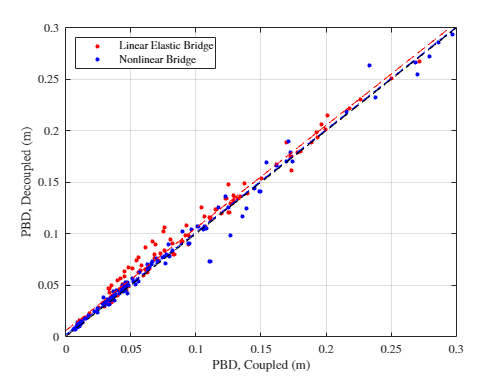

% Coupled/Decoupled 
close all
indices1 = find((SummTable.cf == 1.0) .* (SummTable.bridgemodel == 0.0));  % Coupled
indices2 = find((SummTable.cf == 1.0) .* (SummTable.bridgemodel == 1.0));  % Decoupled
indices3 = find((SummTable.cf == 0.0) .* (SummTable.bridgemodel == 0.0));  % Coupled
indices4 = find((SummTable.cf == 0.0) .* (SummTable.bridgemodel == 1.0));  % Decoupled


reg1 = polyfit(SummTable(indices1,:).pbd, SummTable(indices3,:).pbd, 1);
reg2 = polyfit(SummTable(indices2,:).pbd, SummTable(indices4,:).pbd, 1);


plot(SummTable(indices1,:).pbd, SummTable(indices3,:).pbd, 'r.', ...
     SummTable(indices2,:).pbd, SummTable(indices4,:).pbd, 'b.', ...
     [0, 3], polyval(reg1, [0,3]), 'r--', ...
     [0, 3], polyval(reg2, [0,3]), 'b--', ...
     [0, 3], [0, 3], 'k--', MarkerSize=10.0), axis([0 0.3 0 0.3]),...
xlabel('PBD, Coupled (m)'), ylabel('PBD, Decoupled (m)'), grid on,...
legend('Linear Elastic Bridge', 'Nonlinear Bridge', Location='northwest')

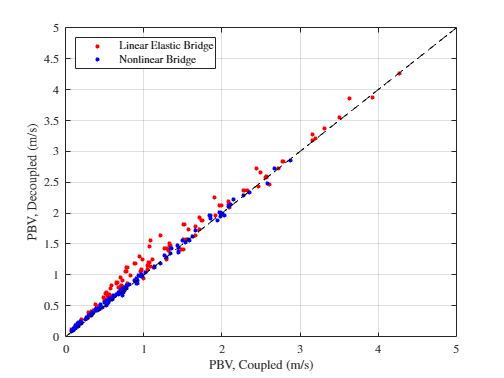

close all
indices1 = find((SummTable.cf == 1.0) .* (SummTable.bridgemodel == 0.0));  % Coupled, Linear
indices2 = find((SummTable.cf == 1.0) .* (SummTable.bridgemodel == 1.0));  % Coupled, Nonlinear
indices3 = find((SummTable.cf == 0.0) .* (SummTable.bridgemodel == 0.0));  % Decoupled, Linear
indices4 = find((SummTable.cf == 0.0) .* (SummTable.bridgemodel == 1.0));  % Decoupled, Nonlinear


reg1 = polyfit(SummTable(indices1,:).pbv, SummTable(indices3,:).pbv, 1);
reg2 = polyfit(SummTable(indices2,:).pbv, SummTable(indices4,:).pbv, 1);

plot(SummTable(indices1,:).pbv, SummTable(indices3,:).pbv, 'r.', ...
     SummTable(indices2,:).pbv, SummTable(indices4,:).pbv, 'b.', ...
     [0, 5], [0, 5], 'k--', MarkerSize=10.0), axis([0 5.0 0 5.0]), ...
     xlabel('PBV, Coupled (m/s)'), ylabel('PBV, Decoupled (m/s)'), grid on, ...
     legend('Linear Elastic Bridge', 'Nonlinear Bridge', Location='northwest')

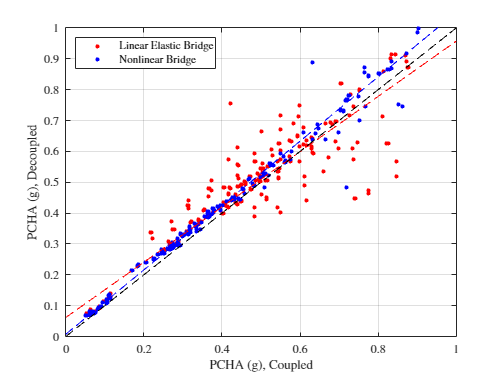

close all
indices1 = find((SummTable.cf == 1.0) .* (SummTable.bridgemodel == 0.0));  % Coupled
indices2 = find((SummTable.cf == 1.0) .* (SummTable.bridgemodel == 1.0));  % Decoupled
indices3 = find((SummTable.cf == 0.0) .* (SummTable.bridgemodel == 0.0));  % Coupled
indices4 = find((SummTable.cf == 0.0) .* (SummTable.bridgemodel == 1.0));  % Decoupled


reg1 = polyfit(SummTable(indices1,:).pcha / 9.81, SummTable(indices3,:).pcha / 9.81, 1);
reg2 = polyfit(SummTable(indices2,:).pcha / 9.81, SummTable(indices4,:).pcha / 9.81, 1);


plot(SummTable(indices1,:).pcha / 9.81, SummTable(indices3,:).pcha / 9.81, 'r.', ...
     SummTable(indices2,:).pcha / 9.81, SummTable(indices4,:).pcha / 9.81, 'b.', ...
     [0, 1], polyval(reg1, [0,1]), 'r--', ...
     [0, 1], polyval(reg2, [0,1]), 'b--', ...
     [0, 1], [0, 1], 'k--', MarkerSize=10.0), axis([0 1 0 1]), ...
     xlabel('PCHA (g), Coupled'), ylabel('PCHA (g), Decoupled'), grid on, ...
     legend('Linear Elastic Bridge', 'Nonlinear Bridge', Location='northwest')